# Introducing iset3d calculations

Rendera the sphere scene to illustrate the basic read, edit, write cycle.

**See also:**

    t_piIntro_*, piRecipeDefault, @recipe

## Initialize ISET and Docker

Start up ISET and check that docker is configured 

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the recipe

thisR = piRecipeDefault('scene name','sphere');

Read 1 materials.
Read 1 textures.
***Scene parsed.



% Add a point light, needed by this scene.
pointLight = piLightCreate('point','type','point','cameracoordinate', true);
thisR.set('light','add',pointLight);

## Set up the render quality

There are many different parameters that can be set. This is the just an introductory script, so we do a minimal number of parameters. Much of what is described in other scripts expands on this section.

thisR.set('film resolution',[192 192]);
thisR.set('rays per pixel',128);
thisR.set('n bounces',1); % Number of bounces

## Save the recipe and render

piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/sphere/sphere.pbrt



% There is no lens, just a pinhole.  In that case, we are rendering a
% scene. If we had a lens, we would be rendering an optical image.
[scene, result] = piRender(thisR);

Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/sphere/sphere_depth.pbrt
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/sphere" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/sphere":"/Users/wandell/Documents/MATLAB/iset3d/local/sphere" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/sphere/renderings/sphere.dat /Users/wandell/Documents/MATLAB/iset3d/local/sphere/sphere.pbrt
*** Rendering time for sphere:  14.8 sec ***

  Reading image h=192 x w=192 x 31 spectral planes.
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/sphere" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/sphere":"/Users/wandell/Documents/MATLAB/iset3d/local/sphere" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/sphere/renderings/sphere_depth.dat /Users/wande

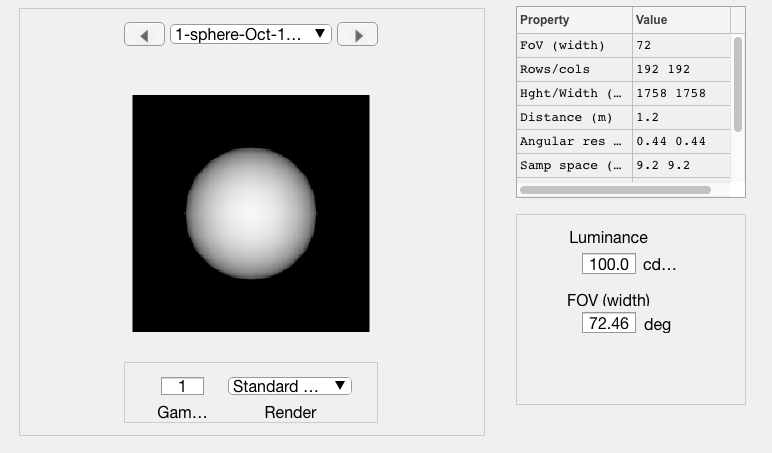

sceneWindow(scene);

## By default, we also compute the depth map

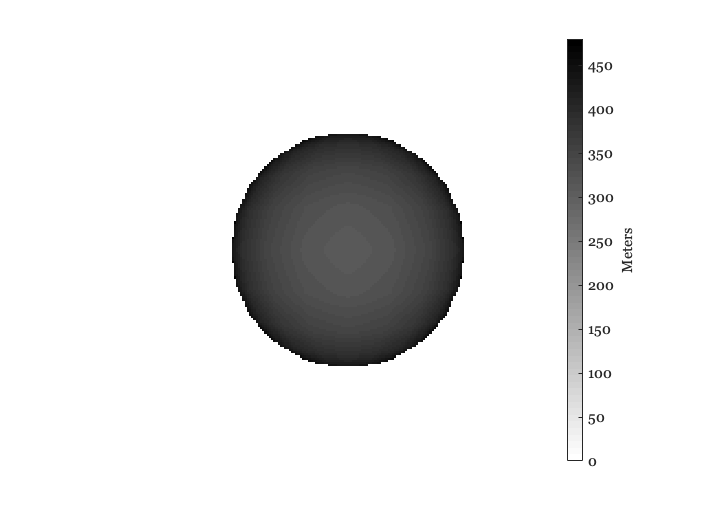

scenePlot(scene,'depth map');

## A bluish light

You can also try a different light, which is more blue and distant 

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/sphere/sphere.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/sphere" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/sphere":"/Users/wandell/Documents/MATLAB/iset3d/local/sphere" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/sphere/renderings/sphere.dat /Users/wandell/Documents/MATLAB/iset3d/local/sphere/sphere.pbrt
*** Rendering time for sphere:  16.2 sec ***

  Reading image h=192 x w=192 x 31 spectral planes.


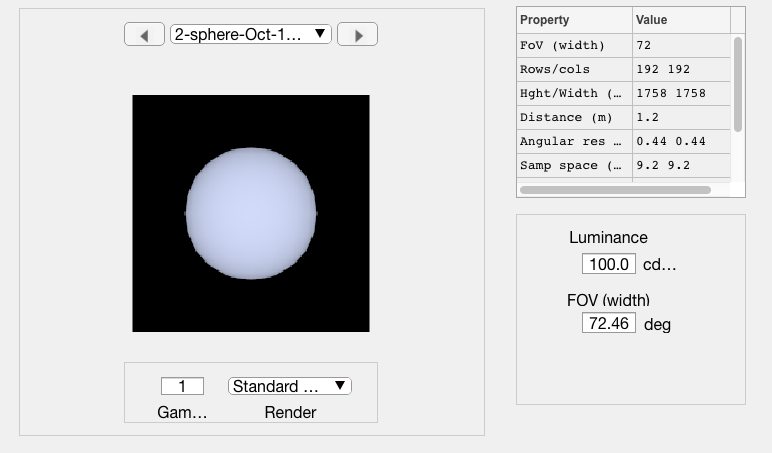

distantLight = piLightCreate('distant','type','distant',  'spd', [9000 0.001],  'cameracoordinate', true);
thisR.set('light','delete',pointLight.name);
thisR.set('light','add',distantLight);

% This is a faster way to Write Render and Show
piWRS(thisR);